# RW9

file:///C:/nobackup/_phd_work/_battery_soh/_dataset/NASA_Randomized%20Battery%20Usage%20Data%20Set/Battery_Uniform_Distribution_Charge_Discharge_DataSet_2Post/README_RW_ChargeDischarge_RT.html

# Description of Room Temperature Random Walk Charging and Discharging Data Sets

*Author: Brian Bole****2015-03-25***

**Point of Contact:** [**chetan.s.kulkarni@nasa.gov**](mailto:chetan.s.kulkarni@nasa.gov)

## Experiment Description

A set of four 18650 Li-ion batteries (Identified as RW9, RW10, RW11 and RW12) were continuously operated using a sequence of **charging and discharging currents between -4.5A and 4.5A**. This type of charging and discharging operation is referred to here as random walk (RW) operation. **Each of the loading periods lasted 5 minutes, and after 1500 periods (about 5 days) a series of reference charging and discharging cycles were performed in order to provide reference benchmarks for battery state health.**

This document explains the structure of the battery data sets. Analysis of a similar dataset is published in:

*Brian Bole, Chetan Kulkarni, and Matthew Daigle, “Adaptation of an Electrochemistry-based Li-Ion Battery Model to Account for Deterioration Observed Under Randomized Use”, in the proceedings of the Annual Conference of the Prognostics and Health Management Society, 2014*

Please cite this paper when using this dataset.

## Files:

RW9.mat -> A Matlab data structure for Battery #RW9

RW9.Rda -> An R data frame containing the same data as the Matlab data structure

RW10.mat -> A Matlab data structure for Battery #RW10

RW10.Rda -> An R data frame containing the same data as the Matlab data structure

RW11.mat -> A Matlab data structure for Battery #RW11

RW11.Rda -> An R data frame containing the same data as the Matlab data structure

RW12.mat -> A Matlab data structure for Battery #RW12

RW12.Rda -> An R data frame containing the same data as the Matlab data structure

MatlabSamplePlots.m -> An example Matlab code that recreates all of the plots shown in the README document

## Data Structure:

Each of the .mat files contains a Matlab data structure called “data”.

The top level of this structure contains 3 fields:

- **procedure** (A string naming the experimental procedure)

- **description** (A more detailed text description of the experimental procedure)

- **step** (An array of structs containing cycling data)

           Within the **step** array you will find a struct with the following fields:

- **comment** (string description of step)

- **type** (one character identifier of step: ‘C’ = Charging, ‘D’ = Discharging, ‘R’ = Resting (current = 0))

- **relativeTime** (vector of sample time in seconds, referenced to the beginning of the current step)

- **time** (vector of sample time in seconds, referenced to the beginning of the experiment)

- **voltage** (vector of sample voltage in units of Volts)

- **current** (vector of sample current in units of Amps)

- **temperature** (vector of sample temperature in units of degrees C)

- **date** (date and time at which the current step was started in dd-Mon-yyyy HH:MM:SS format)

Each of the .Rda files contains the same information as the Matlab data files. The step data structure in each .Rda file is formated as a dataframe wherein each row represents a unique charging, discharging, or resting step in the battery cycling experiment.

**Batteries are cycled using three types of reference profiles:**

- **A low current discharge at 0.04A** is used to observe the batteries open circuit voltage as a function of SOC

- This profile is identified in the **step** data structure with the **comment** field equal to **“low current discharge at 0.04A”**

- Resting periods that occur immediately before and after the low current discharge are identified with the **comment** field = **“rest prior low current discharge”** and **comment** field = **“rest post low current discharge”** respectively

- A reference charge and discharge cycle is used to observe the battery capacity after every 1500 RW steps cycles

- **Batteries are first charged at 2A (constant current), until they reach 4.2V, at which time the charging switches to a constant voltage mode and continues charging the batteries until the charging current falls below 0.01A.**

- This step is identified with the **comment** field = **“reference charge”**

- Batteries are then rested for a period of time with no current draw

- This step is identified with the **comment** field = **“rest post reference charge”**

- Batteries are then discharged at **2A until the battery voltage crosses 3.2V**

- This step is identified with the **comment** field = **“reference discharge”**

- Batteries are then rested for a period of time

- This step is identified with the **comment** field = **“rest post reference discharge”**

- A pulsed current discharge of fully charged batteries is performed after every 3000 RW steps in order to benchmark changes to battery transient dynamics. The pulsed current discharge consist of a **1A load applied for 10 minutes, followed by 20 minutes of no load**.

- This discharging profile is identified by alternating steps of **comment** = **“pulsed load (rest)”** and **comment** = **“pulsed load (discharge)”**

- A resting period after either a pulsed discharge or a pulsed charge is denoted by **comment** = **“rest post pulsed load or charge”**

- A pulsed current charge of recently discharged batteries is performed after every 3000 RW cycles in order to benchmark changes to battery transient dynamics. The pulsed current charge consists of a 1A charging current applied for 10 minutes, followed by 20 minutes of rest.

- This charging profile is identified by alternating steps of **comment** = **“pulsed charge (rest)”** and **comment** = **“pulsed charge (charge)”**

- A resting period after either a pulsed discharge or a pulsed charge is denoted by **comment** = **“rest post pulsed load or charge”**

**The random walk (RW) mode of battery cycling consists of:**

- Selecting a charging or discharging current at random from the set {-4.5A, -3.75A, -3A, -2.25A, -1.5A, -0.75A, 0.75A, 1.5A, 2.25A, 3A, 3.75A, 4.5A}. Negative currents are associated with charging and positive currents indicate discharging.

- The selected current setpoint is applied until either the battery voltage goes outside the range (3.2V - 4.2V) or 5 minutes has passed.

- These steps are identified with the **comment** field = **“discharge (random walk)”** and **comment** field = **“charge (random walk)”**

- After each charging or discharging period, there will be a <1s period of rest while a new charging or discharging current setpoint is selected.

- This steps is identified with the **comment** field = **“rest (random walk)”**

- Steps 2 and 3 are repeated 1500 times, then characterization cycles are preformed to benchmark battery state of health.

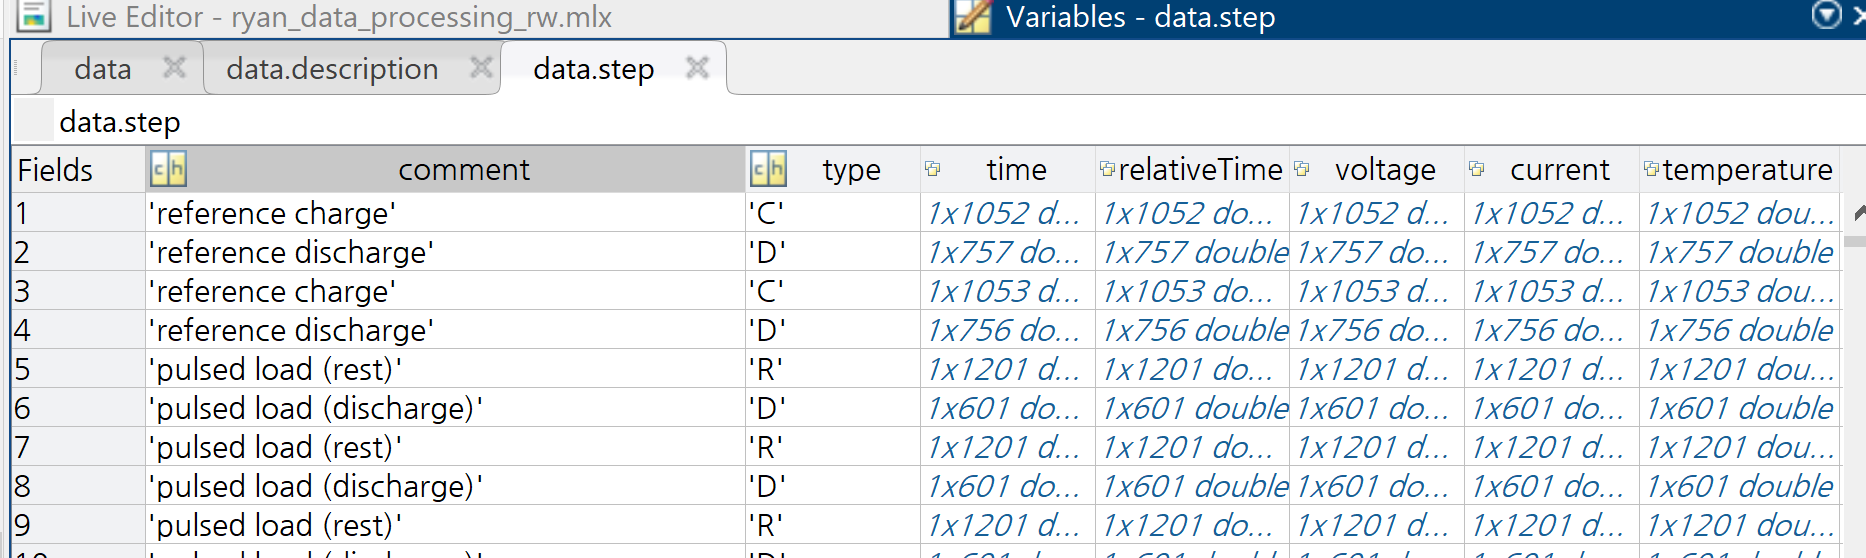

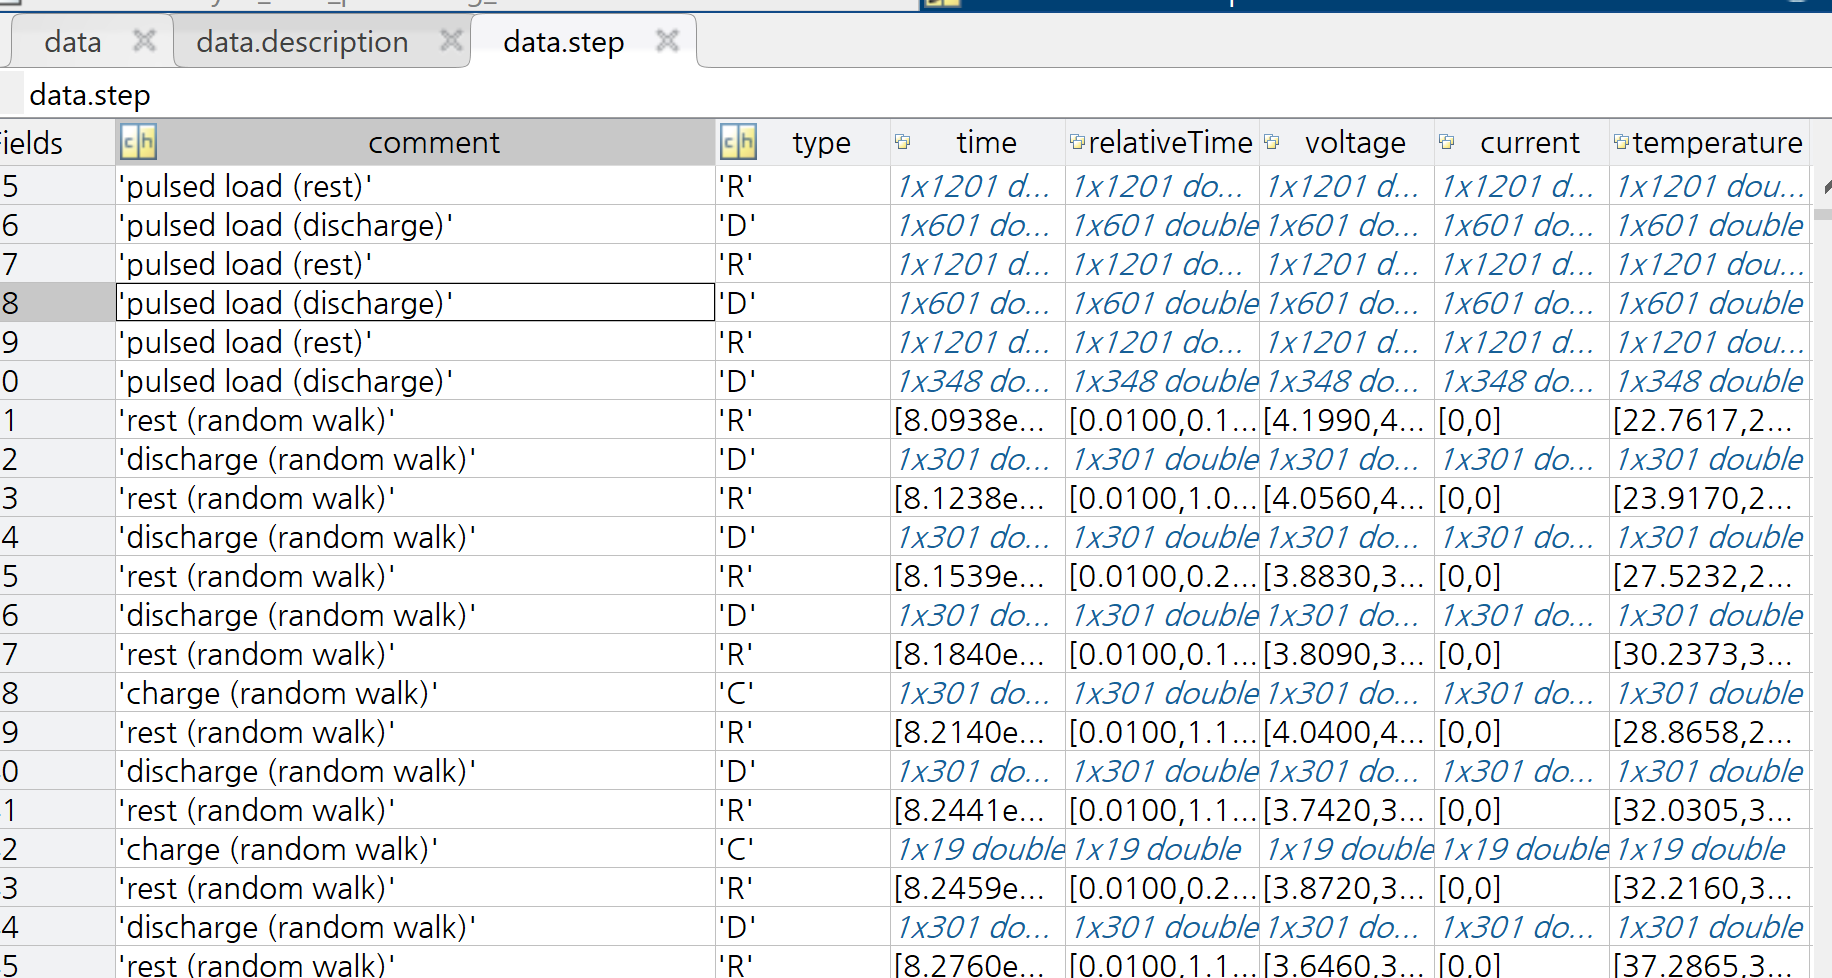

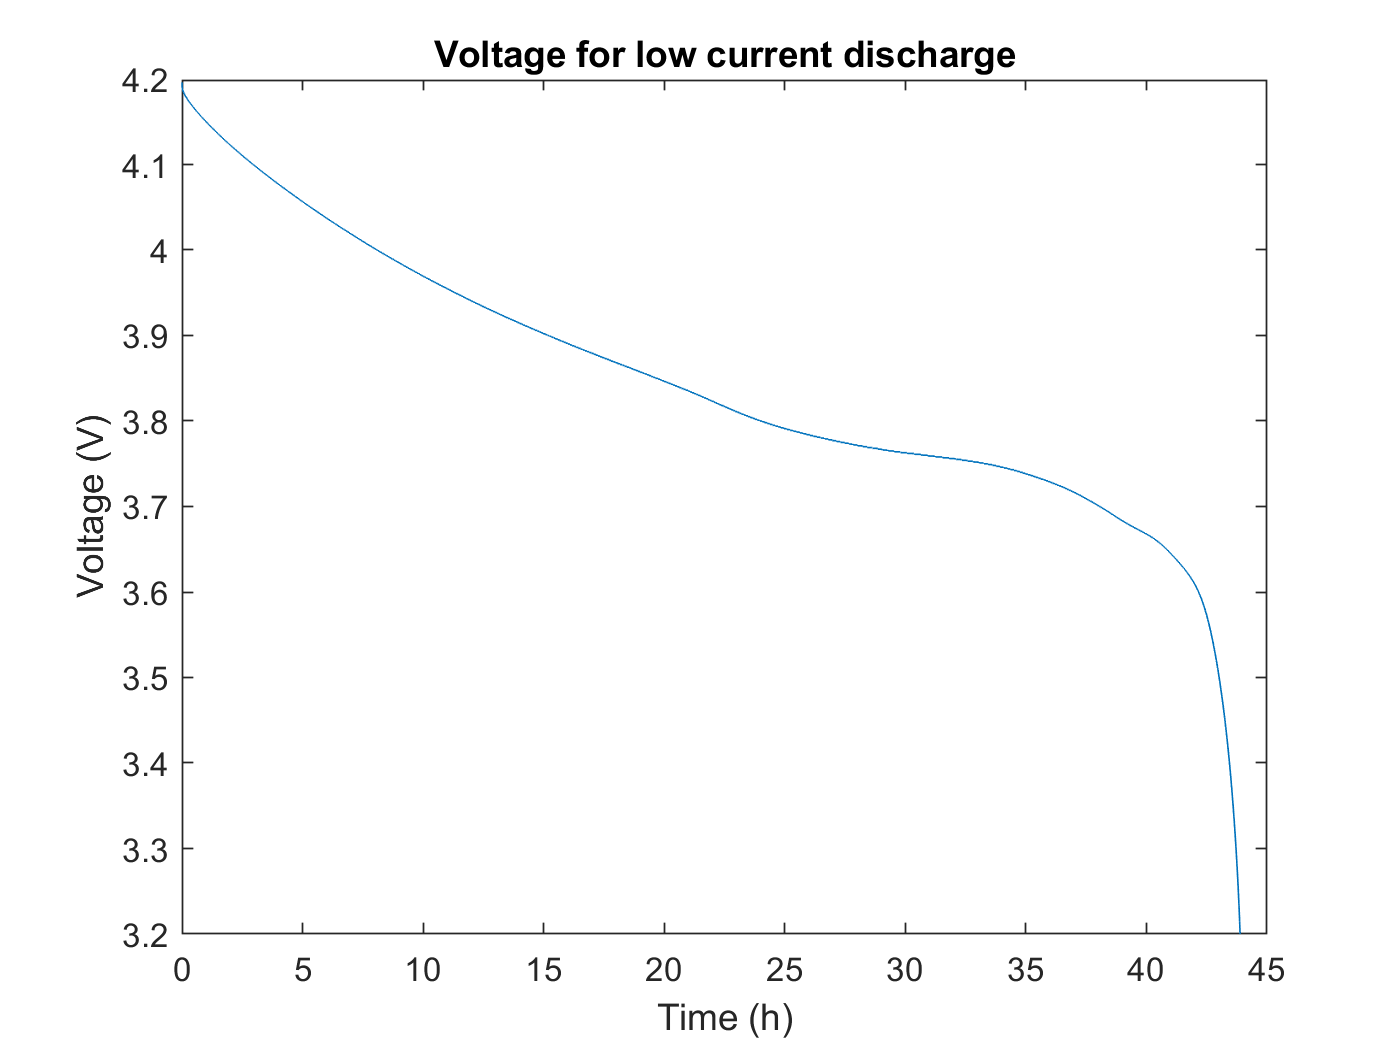

% example script that recreates the plots shown in the README document
close all;
clear all;

% Change this data file name below to plot different files
load('../RW9')

%% First we show a sample plot of the low current discharge data

steps = data.step; % save steps array to new variable

% search for instances of low current discharge step
inds = []; % initialize index array
for(i=1:length(steps)) 
    if(strcmp(data.step(i).comment,'low current discharge at 0.04A')) 
        inds = [inds, i];
    end
end

% plot data from first low current discharge step
RT = steps(inds(1)).relativeTime/3600; % relative time in hours
V = steps(inds(1)).voltage; % voltage
I = steps(inds(1)).current; % current

figure % plot voltage profile
plot(RT,V)
title('Voltage for low current discharge = 0.04A')
xlabel('Time (h)');
ylabel('Voltage (V)');

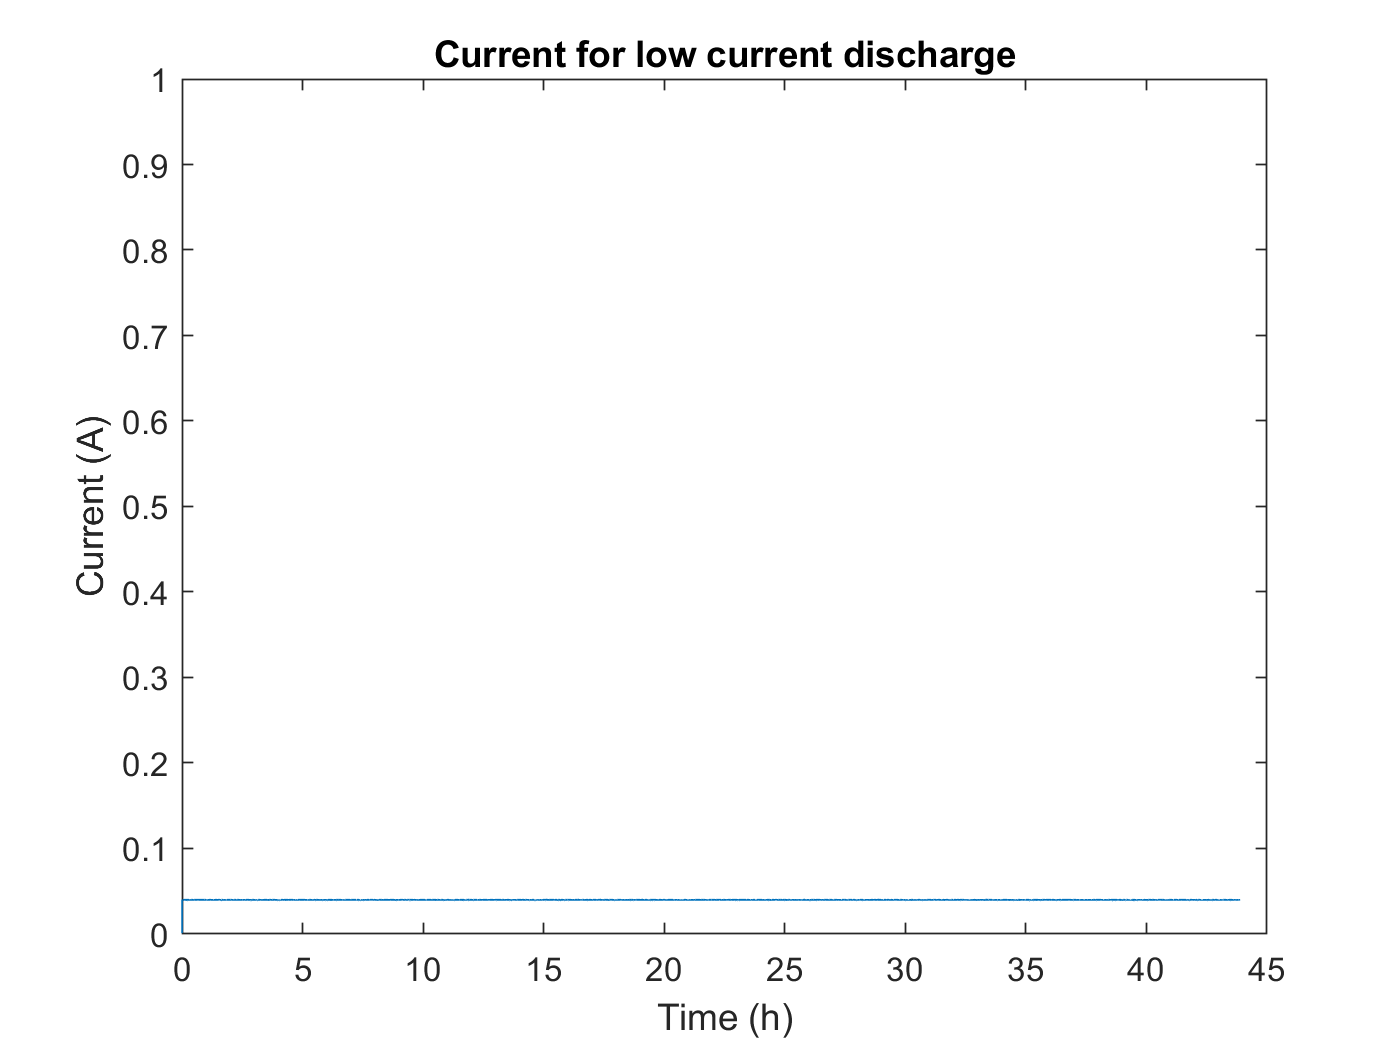


figure % plot current profile
plot(RT,I)
title('Current for low current discharge = 0.04A')
ylim([0,1])
xlabel('Time (h)');
ylabel('Current (A)');

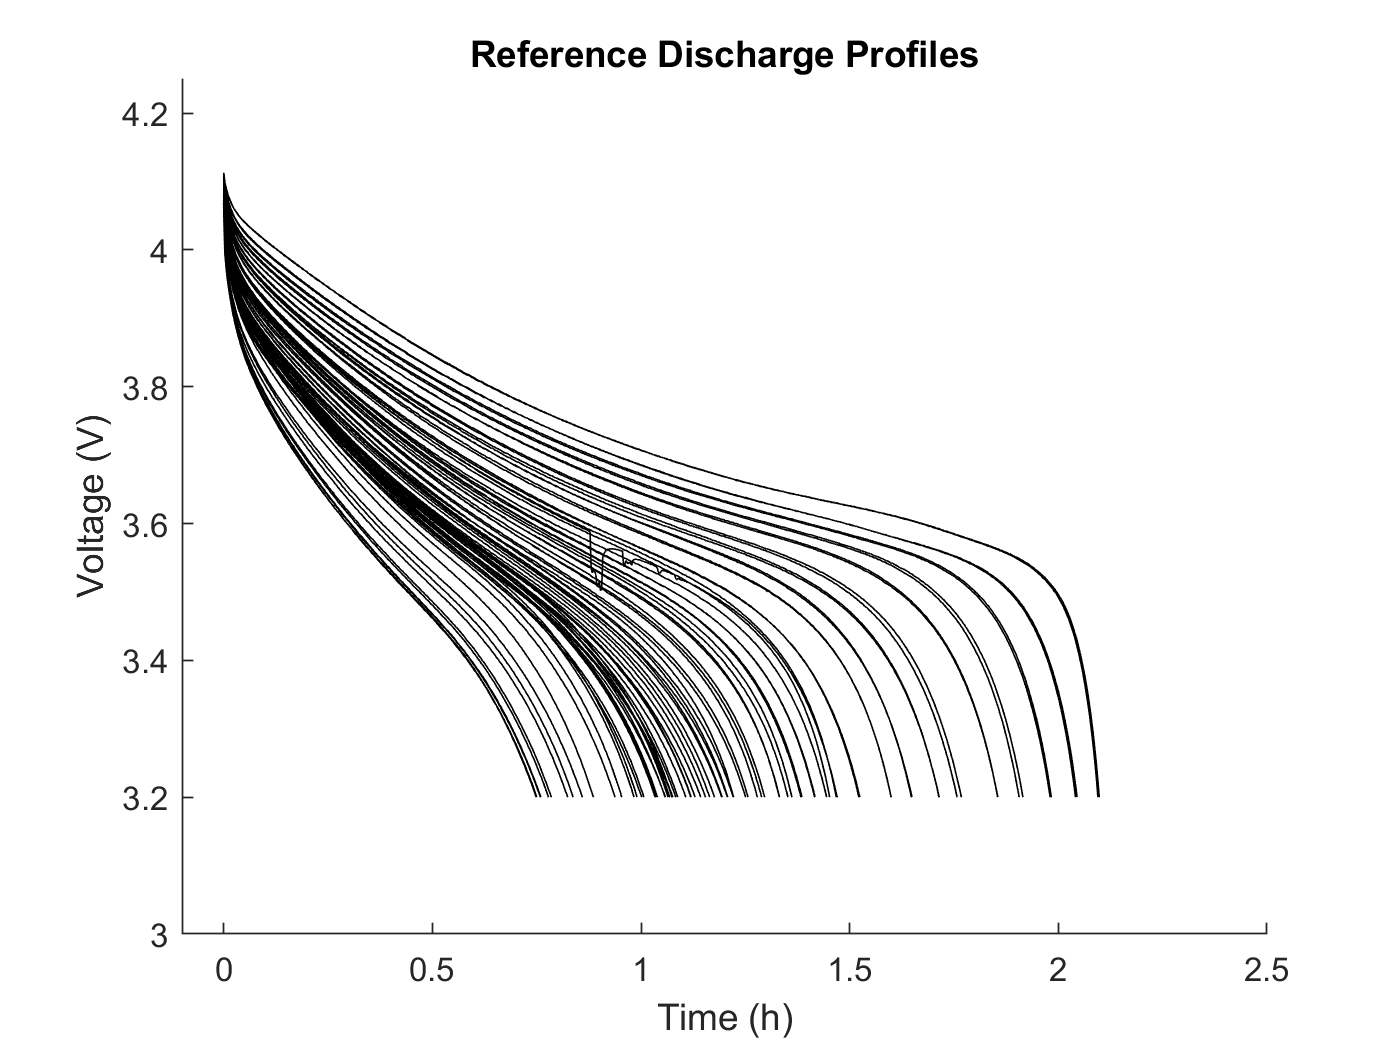



%% Next, the constant load profiles that are run after every 50 random walk 
% discharge cycles are plotted using

% initialize plot
figure, hold on
xlim([-.1,2.5])
ylim([3,4.25])
xlabel('Time (h)');
ylabel('Voltage (V)');
title('Reference Discharge Profiles = 2A until 3.2V')

for i = 1:length(steps) % search through the array of step structures
    if strcmp(steps(i).comment,'reference discharge') 
        RT = steps(i).relativeTime/3600; % relative time in hours
        V = steps(i).voltage; % voltage
        plot(RT,V,'k')
    end
end

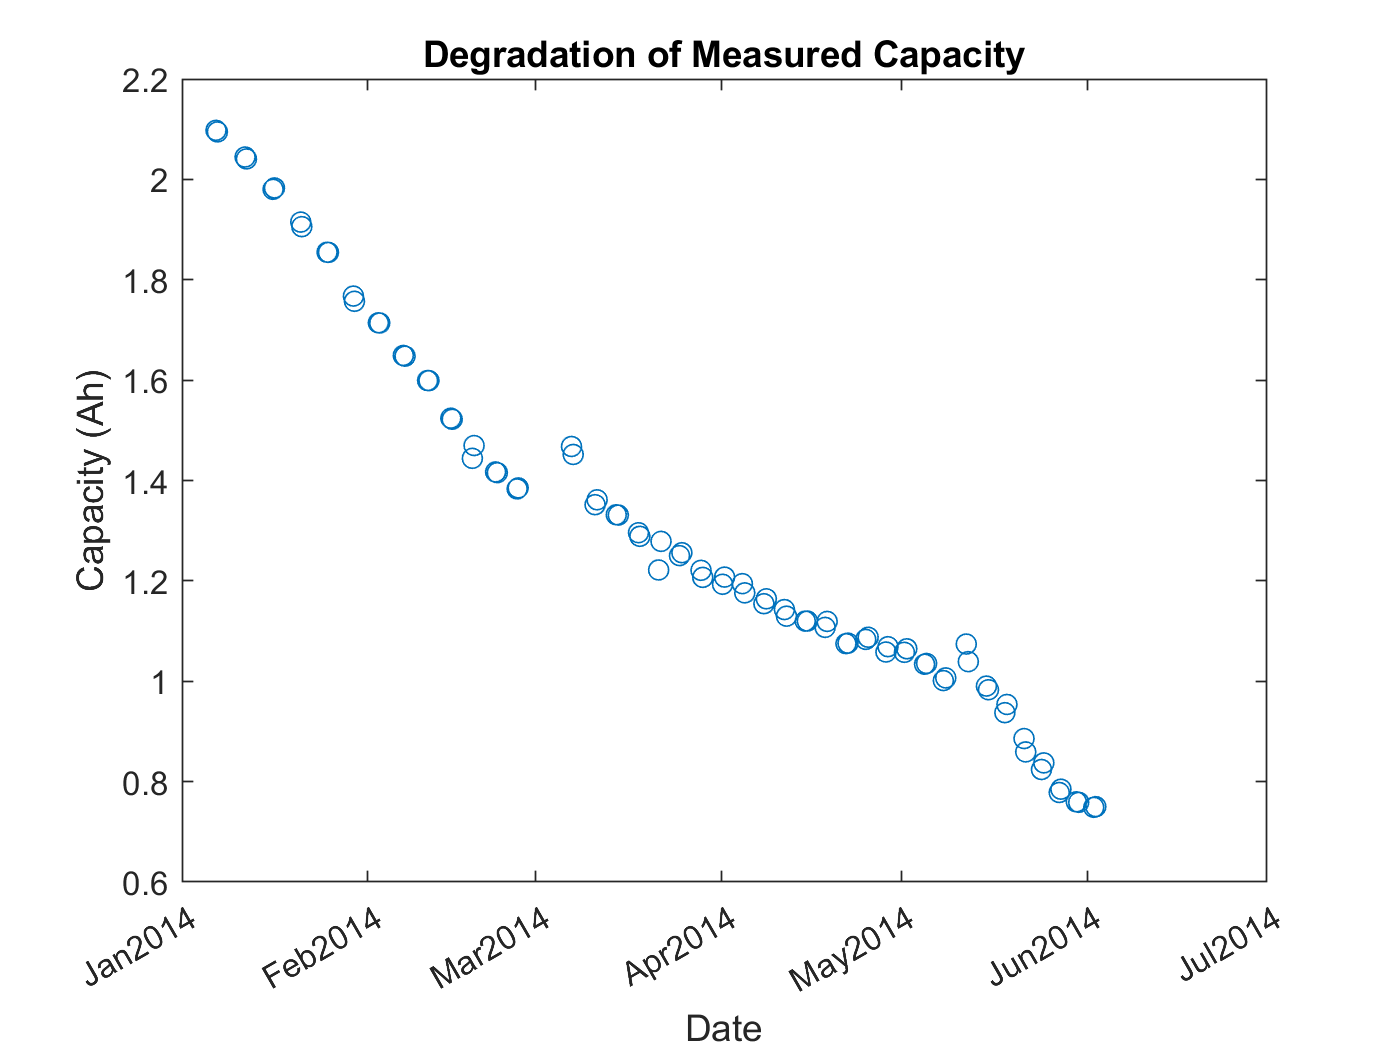



%% We can benchmark the battery뭩 capacity by integrating current over the 
% reference cycles. The next plot shows this capacity measurement vs date.

counter = 0; % initialize counters

for i = 1:length(steps) % search through the array of step structures
    if strcmp(steps(i).comment,'reference discharge') 
        counter = counter+1;

        % save the date of this reference discharge step
        date(counter) = datenum(steps(i).date);
        
        % save the battery capacity measured by integrating current 
        capacity(counter) = trapz(steps(i).relativeTime/3600,data.step(i).current);
    end
end

% plot the data
figure
plot(date,capacity,'o')
datetick('x','mmmyyyy')
xlabel('Date');
ylabel('Capacity (Ah)');
title('Degradation of Measured Capacity')

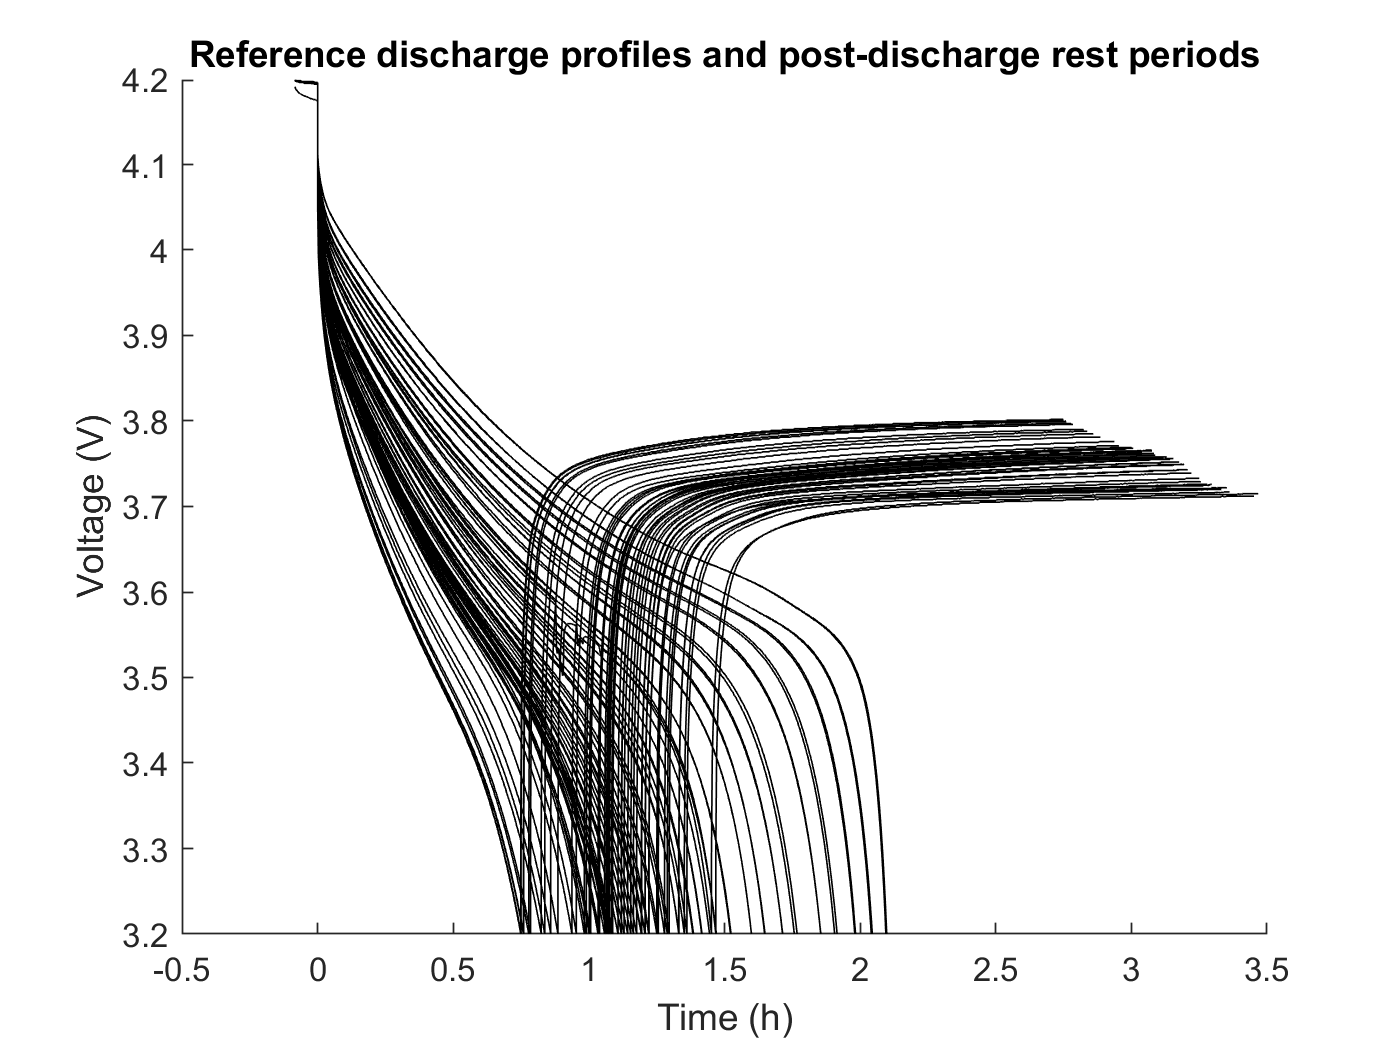


%% The next code snippet shows how the resting periods after each reference 
% discharge can be grouped with the corresponding reference discharge cycle 
% and added to the plot above. 

% initialize Reference Discharge Struct that will hold indexes of reference
% discharge steps and the rest steps that come imediately before and after
RefDis.repition{1}.indexes = 0;

% initialize loop parameters
counter = 0;
for i = 1:length(data.step)
    if strcmp(steps(i).comment,'reference discharge')
        counter = counter+1;
        if strcmp(steps(i-1).comment,'rest post reference charge')
            RefDis.repition{counter}.indexes = [i-1, i];
        else
            RefDis.repition{counter}.indexes = i;
        end
    end
    
    if strcmp(steps(i).comment,'rest post reference discharge')
        RefDis.repition{counter}.indexes = [RefDis.repition{counter}.indexes, i];
    end
end

% now plot each of the grouped reference discharge cycles
figure, hold on
for i = 1:length(RefDis.repition)
    % stitch together all of the substeps identified in the repitition
    % field
    step = steps(RefDis.repition{i}.indexes(1));
    
    % if the first index is a rest period, then make it end at relativeTime == 0 
    if(strcmp(step.comment,'rest post reference charge'))
        step.relativeTime = step.relativeTime - step.relativeTime(end); 
    end
    
    for j = 2:length(RefDis.repition{i}.indexes)
        step.relativeTime = [step.relativeTime step.relativeTime(end)+steps(RefDis.repition{i}.indexes(j)).relativeTime];
        step.voltage = [step.voltage steps(RefDis.repition{i}.indexes(j)).voltage];
        step.current = [step.current steps(RefDis.repition{i}.indexes(j)).current];
        step.temperature = [step.temperature steps(RefDis.repition{i}.indexes(j)).temperature];
    end
    
    plot(step.relativeTime/3600,step.voltage,'k')
    title('Reference discharge profiles and post-discharge rest periods')
    xlabel('Time (h)')
    ylabel('Voltage (V)')
end

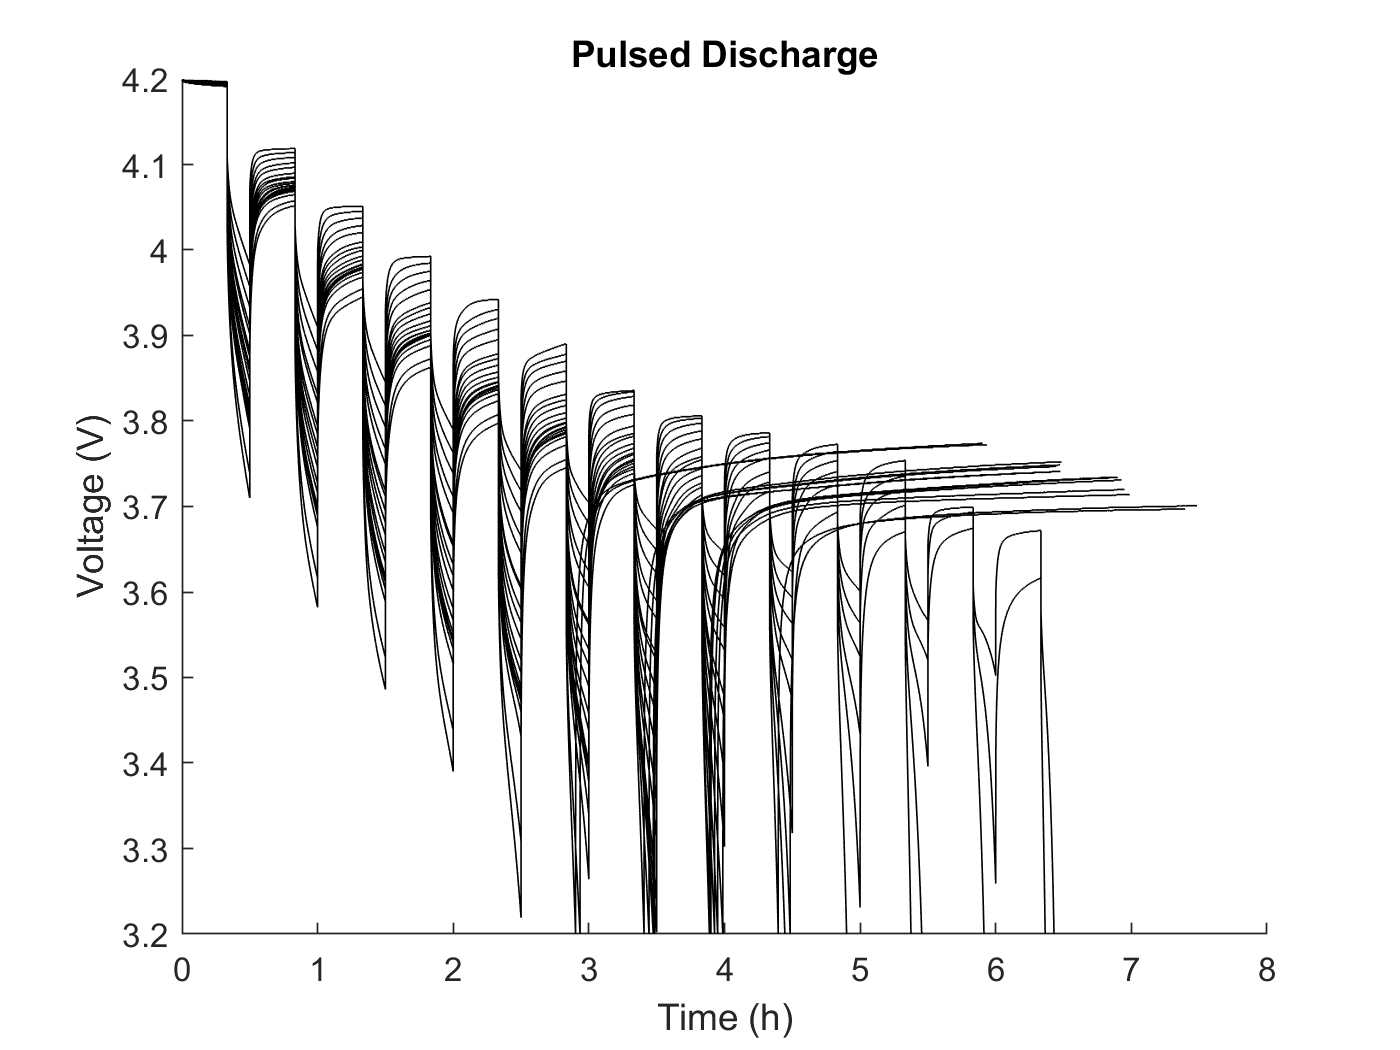


%% Example Plots of Pulsed Load Charging and Discharging Cycles

PulsedDis.repition{1}.indexes = 0;
counter1 = 0;
counter2 = 0;
% find Pulsed Load discharge characterization cycles
for i = 2:length(data.step)
    if (strcmp(data.step(i).comment,'pulsed load (discharge)')...
            || strcmp(data.step(i).comment,'pulsed load (rest)'))  
        % if just starting the pulsed load cycle
        if (strcmp(data.step(i).comment,'pulsed load (rest)') && (~strcmp(data.step(i-1).comment,'pulsed load (discharge)')))  
            counter1 = 1;
            counter2 = counter2+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i;
        else
            counter1 = counter1+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i; 
        end
    end
    if(strcmp(data.step(i).comment,'rest post pulsed load or charge'))
        % check to see if this preceeds a pulsed load (discharge)
        if(strcmp(data.step(i-1).comment,'pulsed load (discharge)'))
            counter1 = counter1+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i;
        end
    end
end

% now plot each of the grouped pulsed load discharge cycles
figure, hold on
for i = 1:length(PulsedDis.repition)
    % stitch together all of the substeps identified in the repitition
    % field
    step = steps(PulsedDis.repition{i}.indexes(1));
    
    for j = 2:length(PulsedDis.repition{i}.indexes)
        step.relativeTime = [step.relativeTime step.relativeTime(end)+steps(PulsedDis.repition{i}.indexes(j)).relativeTime];
        step.voltage = [step.voltage steps(PulsedDis.repition{i}.indexes(j)).voltage];
        step.current = [step.current steps(PulsedDis.repition{i}.indexes(j)).current];
        step.temperature = [step.temperature steps(PulsedDis.repition{i}.indexes(j)).temperature];
    end
    
    plot(step.relativeTime/3600,step.voltage,'k')
    title('Pulsed Discharge')
    xlabel('Time (h)')
    ylabel('Voltage (V)')
end

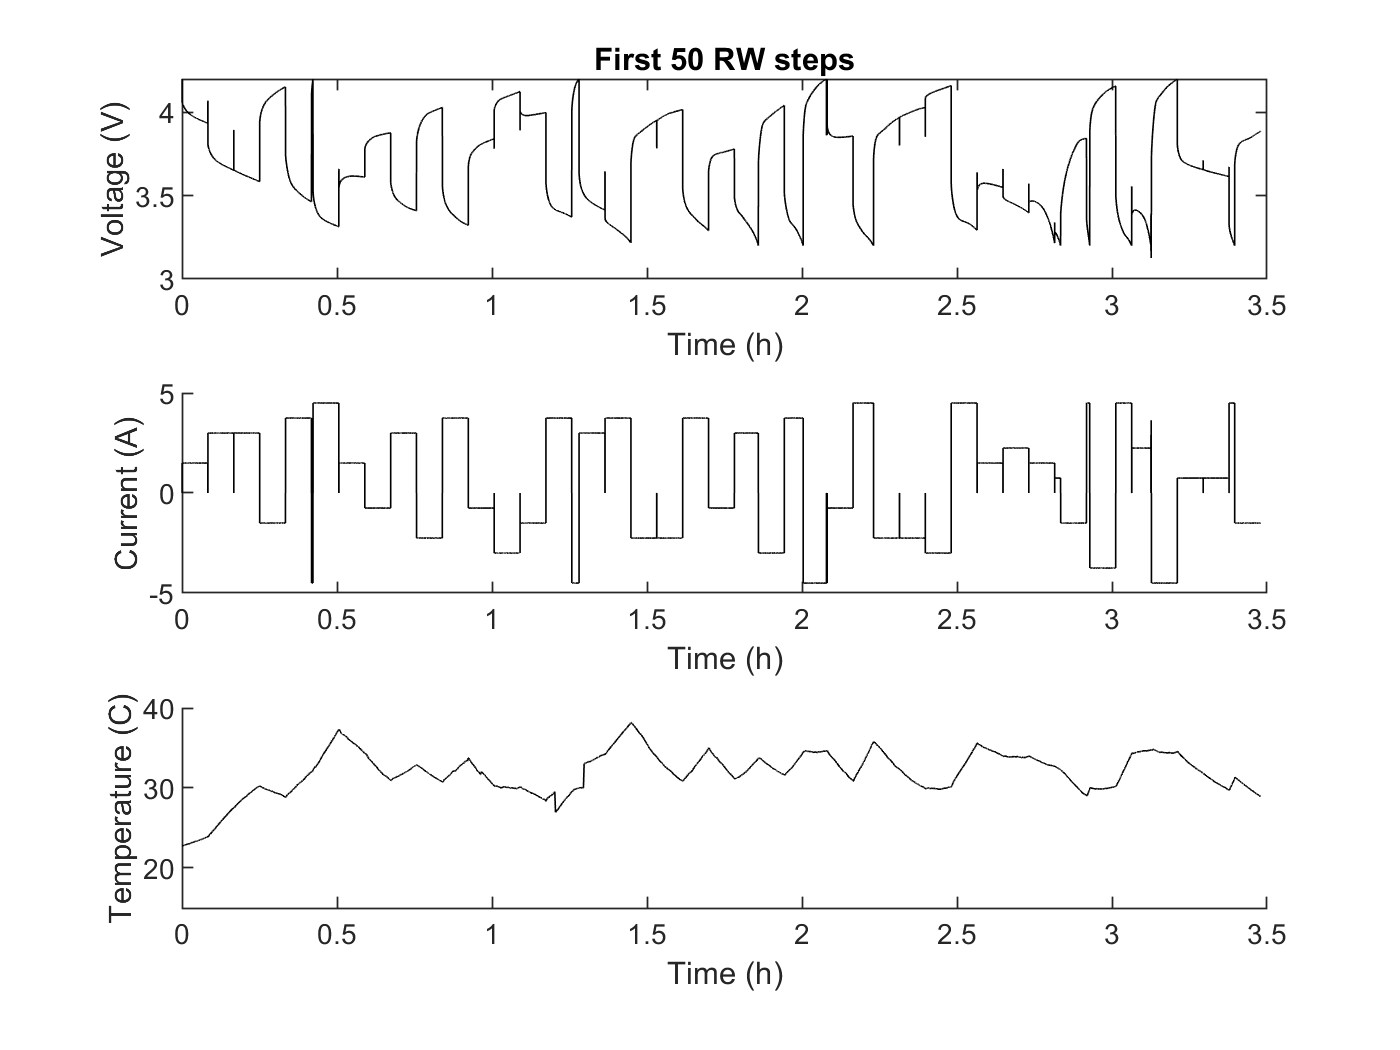


%% The following sample code shows data collected over the first 50 and the 
% last 50 RW steps in the experiment.

RWDis.repition{1}.indexes = 0;
counter1 = 0;
counter2 = 0;
lastStep = -1;
% find indexes of all RW steps
for i = 1:length(steps)
    if (strcmp(steps(i).comment,'discharge (random walk)')||...
            strcmp(steps(i).comment,'rest (random walk)')||...
            strcmp(steps(i).comment,'charge (random walk)'))
        % if there is a break in the step sequence then separate sequence 
        % into new list
        if (i-lastStep > 1)  
            counter1 = 1;
            counter2 = counter2+1;
            RWDis.repition{counter2}.indexes(counter1) = i; 
        else
            counter1 = counter1+1;
            RWDis.repition{counter2}.indexes(counter1) = i; 
        end
       lastStep = i; 
    end    
end
  
% identify index sequence for first 50 RW discharge cycles
inds = RWDis.repition{1}.indexes(1):RWDis.repition{1}.indexes(100);

% stich all of the indexed steps together
step = steps(inds(1));
for i = 2:length(inds)
    step.relativeTime = [step.relativeTime step.relativeTime(end)+steps(inds(i)).relativeTime];
    step.voltage = [step.voltage steps(inds(i)).voltage];
    step.current = [step.current steps(inds(i)).current];
    step.temperature = [step.temperature steps(inds(i)).temperature];
end
    
% plot Voltage
figure
subplot(3,1,1)
plot(step.relativeTime/3600,step.voltage,'k')
title(sprintf('First 50 RW steps',i))
xlabel('Time (h)')
ylabel('Voltage (V)')
    
% plot Current
subplot(3,1,2), hold on
plot(step.relativeTime/3600,step.current,'k')
xlabel('Time (h)')
ylabel('Current (A)')

% plot temperature
subplot(3,1,3), hold on
plot(step.relativeTime/3600,step.temperature,'k')
ylim([15, 40])
xlabel('Time (h)')
ylabel('Temperature (C)')

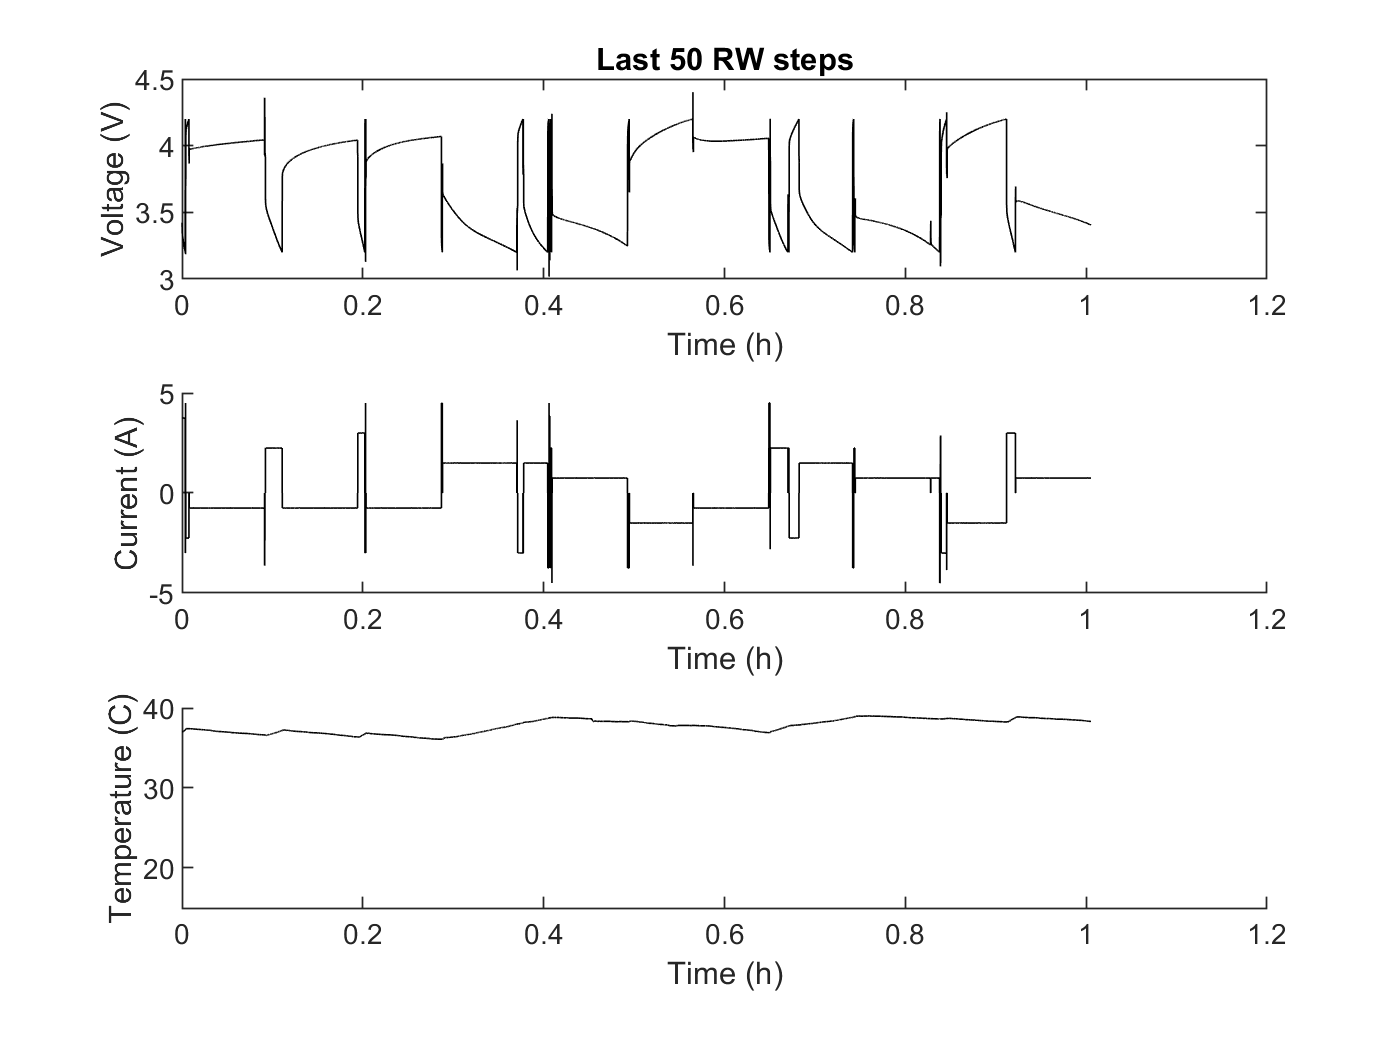


% identify index sequence for last 50 RW discharge cycles
inds = RWDis.repition{end}.indexes(end-100):RWDis.repition{end}.indexes(end);

% stich all of the indexed steps together
step = steps(inds(1));
for i = 2:length(inds)
    step.relativeTime = [step.relativeTime step.relativeTime(end)+steps(inds(i)).relativeTime];
    step.voltage = [step.voltage steps(inds(i)).voltage];
    step.current = [step.current steps(inds(i)).current];
    step.temperature = [step.temperature steps(inds(i)).temperature];
end
    
% plot Voltage
figure
subplot(3,1,1)
plot(step.relativeTime/3600,step.voltage,'k')
title(sprintf('Last 50 RW steps',i))
xlabel('Time (h)')
ylabel('Voltage (V)')
    
% plot Current
subplot(3,1,2), hold on
plot(step.relativeTime/3600,step.current,'k')
xlabel('Time (h)')
ylabel('Current (A)')

% plot temperature
subplot(3,1,3), hold on
plot(step.relativeTime/3600,step.temperature,'k')
ylim([15, 40])
xlabel('Time (h)')
ylabel('Temperature (C)')

[https://github.com/imrenagi/B12-Electronic-Prognostic/blob/master/Battery_Uniform_Distribution_Charge_Discharge_DataSet_2Post/plotall.m](https://github.com/imrenagi/B12-Electronic-Prognostic/blob/master/Battery_Uniform_Distribution_Charge_Discharge_DataSet_2Post/plotall.m)

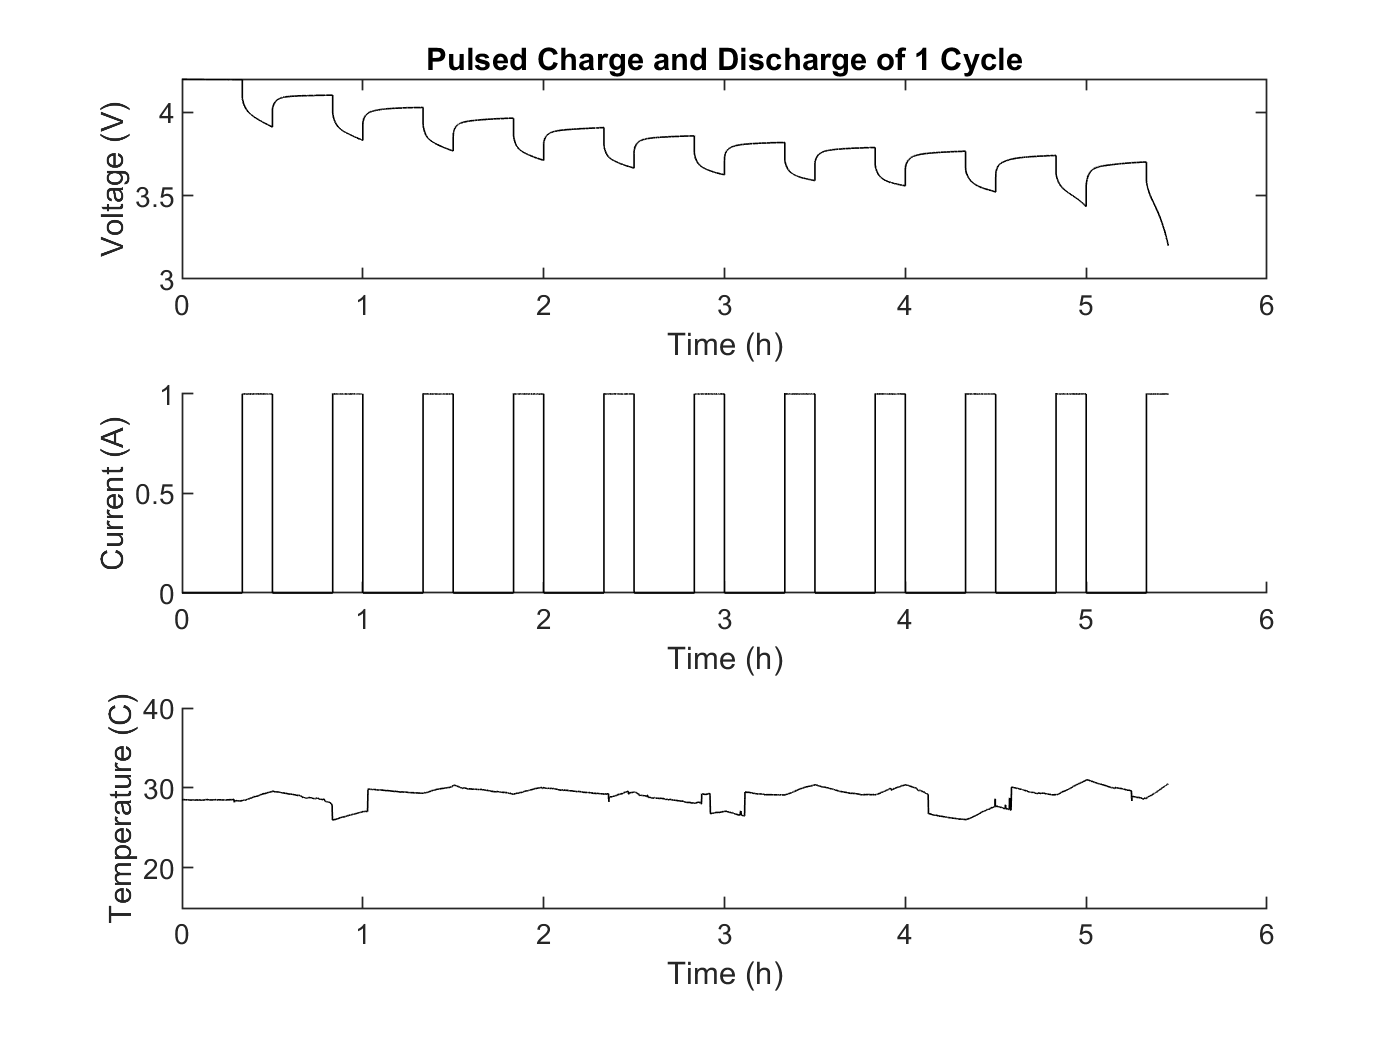

%% Example Plots of Pulsed Load Charging and Discharging Cycles

PulsedDis.repition{1}.indexes = 0;
counter1 = 0;
counter2 = 0;
% find Pulsed Load discharge characterization cycles
for i = 2:length(data.step)
    if (strcmp(data.step(i).comment,'pulsed load (discharge)')...
            || strcmp(data.step(i).comment,'pulsed load (rest)'))  
        % if just starting the pulsed load cycle
        if (strcmp(data.step(i).comment,'pulsed load (rest)') && (~strcmp(data.step(i-1).comment,'pulsed load (discharge)')))  
            counter1 = 1;
            counter2 = counter2+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i;
        else
            counter1 = counter1+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i; 
        end
    end
    if(strcmp(data.step(i).comment,'rest post pulsed load or charge'))
        % check to see if this preceeds a pulsed load (discharge)
        if(strcmp(data.step(i-1).comment,'pulsed load (discharge)'))
            counter1 = counter1+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i;
        end
    end
end

% now plot each of the grouped pulsed load discharge cycles
figure, hold on
% for i = 1:length(PulsedDis.repition)
for i = 4:4
    % stitch together all of the substeps identified in the repitition
    % field
    step = steps(PulsedDis.repition{i}.indexes(1));
    
    for j = 2:(length(PulsedDis.repition{i}.indexes))
        step.relativeTime = [step.relativeTime step.relativeTime(end)+steps(PulsedDis.repition{i}.indexes(j)).relativeTime];
        step.voltage = [step.voltage steps(PulsedDis.repition{i}.indexes(j)).voltage];
        step.current = [step.current steps(PulsedDis.repition{i}.indexes(j)).current];
        step.temperature = [step.temperature steps(PulsedDis.repition{i}.indexes(j)).temperature];
    end
    
%     plot(step.relativeTime/3600,step.voltage,'k')
%     title('Pulsed Discharge')
%     xlabel('Time (h)')
%     ylabel('Voltage (V)')
%     subplot(3,1,1)
%     plot(step.relativeTime/3600,step.voltage,'k')
%     title(sprintf('Pulsed Charge and Discharge of 1 Cycle',i))
%     xlabel('Time (h)')
%     ylabel('Voltage (V)')
% 
%     % plot Current
%     subplot(3,1,2), hold on
%     plot(step.relativeTime/3600,step.current,'k')
%     xlabel('Time (h)')
%     ylabel('Current (A)')
% 
%     % plot temperature
%     subplot(3,1,3), hold on
%     plot(step.relativeTime/3600,step.temperature,'k')
%     ylim([15, 40])
%     xlabel('Time (h)')
%     ylabel('Temperature (C)')
end

    subplot(3,1,1)
    plot(step.relativeTime/3600,step.voltage,'k')
    title(sprintf('Pulsed Charge and Discharge of 1 Cycle',i))
    xlabel('Time (h)')
    ylabel('Voltage (V)')

    % plot Current
    subplot(3,1,2), hold on
    plot(step.relativeTime/3600,step.current,'k')
    xlabel('Time (h)')
    ylabel('Current (A)')

    % plot temperature
    subplot(3,1,3), hold on
    plot(step.relativeTime/3600,step.temperature,'k')
    ylim([15, 40])
    xlabel('Time (h)')
    ylabel('Temperature (C)')

    
% voltCol=transpose(step.voltage(1:20:22938))
% x = step.current * -1
% currCol=transpose(x(1:20:22938))
% tempCol=transpose(step.temperature(1:20:22938))
% timeCol=transpose(floor(step.relativeTime(1:20:22938)))

voltCol=transpose(step.voltage);
x = step.current * -1;
currCol=transpose(x);
tempCol=transpose(step.temperature);
timeCol=transpose(floor(step.relativeTime));

PulseData = struct('time', timeCol, 'voltage', voltCol, 'current', currCol, 'temperature', tempCol);   